# Versuch 4 - Beobachterentwurf und Benutzeroberflächen 

# Praktikum MATLAB®/Simulink® II

## Teilnehmer

#### Teilnehmer 1

Name, Vorname: Gouveia Freitas, Caio Victor

Matrikelnummer: 2328654

#### Teilnehmer 2

Name, Vorname:  Brugnera Silva, Alessandro

Matrikelnummer: 2898524

## GUI Teil 1

Verwenden Sie ihre bisherigen Ergebnisse und kopieren Diese in den heruntergeladenen Ordner. Für die Abgabe  **müssen** auch Ihre alten Dateien im abgegebenen Ordner verbleiben.

Starten Sie den App Designer, laden sie das Projekt *simGUI.mlapp* und testen Sie die GUI, ob die Berechnung des Reglers funktioniert.

appdesigner

### Aufgabe 1

Erweitern Sie die GUI um folgende Funktionen:

- Im dafür vorgesehenen Label Feld (bereits unter dem Namen *ReglerK_CL_Poles* erstellt) sollen die Pole des geschlossenen Regelkreises erscheinen

- Es soll möglich sein, Anfangswerte des Systems vorzugeben

- Hinzufügen eines Buttons, sodass die Simulation im Axensystem des GUIs angezeigt wird

- Hinzufügen eines Buttons, sodass der Ablauf der Animation gestoppt werden kann 

Hinweise: 

Sie sollen Ihre eigenen Funktionen aus Versuch3 verwenden insofern sie sie benötigen. Wenn Sie sich an die vorgegebene Syntax gehalten haben, sollte der Regler in dafür vorgesehenen Feld angezeigt werden.

Achten Sie auf eine gewisse Formatierung, sodass alle Pole im dafür vorgesehenen Feld sichtbar sind. Hierzu können Sie die Pole beispielsweise nach drei Nachkommastellen runden und nicht direkt einen Vektor mittels *num2str* konvertieren, sondern erst die einzelnen Einträge des Vektors konvertieren udn diese zu einem neuen String zusammensetzen.

Zum stoppen des Animation können Sie eine globale Variable verwenden, die in der Callback-Funktion des Stop-Button setzt und in der for-Schleife abgefragt und zurückgesetzt wird.

#### Ihre Antwort:

Keine Antwort notwendig!

**Code und Plots zu Ihrer Antwort:**

% Kein Code erforderlich!

## Beobachter

### Aufgabe 2

Schreiben Sie eine Funktion

*L = berechneBeobachter(A, C, poleBeobachter)*

die den Beobachter nach vorgebbaren Polen auslegt.

edit berechneBeobachter.m

#### Ihre Antwort:

Keine Antwort notwendig!

**Code und Plots zu Ihrer Antwort:**

% Kein Code erforderlich!

### Aufgabe 3

- Erweitern Sie Ihr Simulink-Modell aus Versuch 3, sodass alternativ (über eine Variable wählbar) die Regelung über Zustandsrückführung (Versuch 3) oder Ausgangsrückführung und Beobachter erfolgt. Dazu könnten Sie bspw. einen „Switch“-Block benutzen.

- Erweitern sie Ihre Funktion runPendel so, dass alternativ der Beobachter verwendet werden kann.

              Die neue Syntax der Funktion könnte so aussehen

*[vT, mX, mXobs] = runPendel(stPendel, AP, K, x0, stObs)*

wobei die Struktur stObs alle notwendigen Daten enthalten würde, um den Beobachter in Simulink benutzen zu können. Die Entscheidung, ob der Beobachter verwendet werden soll (und keine Zustandsrückführung) würde in diesem Fall durch die Anzahl der tatsächlich übergebenen Argumente (5 oder 4) getroffen werden.

Der Rückgabewert mXobs enthält die geschätzten Zustände.

- Testen Sie die neue Funktionalität zunächst ohne GUI. Dies können Sie in einem extra Skript machen. Ihre Tests sind für diesen Versuch nicht notwendig zu dokumentieren

Hinweise:

Wird der Beobachter verwendet, muss der Ausgang der s-Function transformiert werden, da dieser alle Systemzustände enthält. Dazu könnte entweder der Ausgang mit einer geeigneten Matrix multipliziert oder der Block „Selector“ aus der Gruppe „Signal Routing“ verwendet werden.

Die Funktion runPendel soll alle notwendigen Schritte zum Starten des Simulink-Modells beinhalten. D. h. diese Funktion sollte auch funktionieren, wenn vorher alle Variablen im Workspace gelöscht werden.

edit runPendel.m

#### Ihre Antwort:

Keine Antwort notwendig!

**Code und Plots zu Ihrer Antwort:**

stPendel = ladePendel();
stObs.switch=1;
stObs.poles = [-10, -12, -13, -14];
stObs.x0=[0,0,0,0];

$$conditions = \left(\begin{array}{cccc} \varphi_{1}=0 & {\mathrm{dphi}}_{1}=0 & \varphi_{2}=0 & {\mathrm{dphi}}_{2}=0 \end{array}\right)$$

AP = [0,0,0,0];

[f, h] = nonlinear_model();
[stObs.A, stObs.B, stObs.C, stObs.D, M_AP] = linearisierung(f,h,AP);

$$conditions = \left(\begin{array}{cccc} \varphi_{1}=0 & {\mathrm{dphi}}_{1}=0 & \varphi_{2}=0 & {\mathrm{dphi}}_{2}=0 \end{array}\right)$$

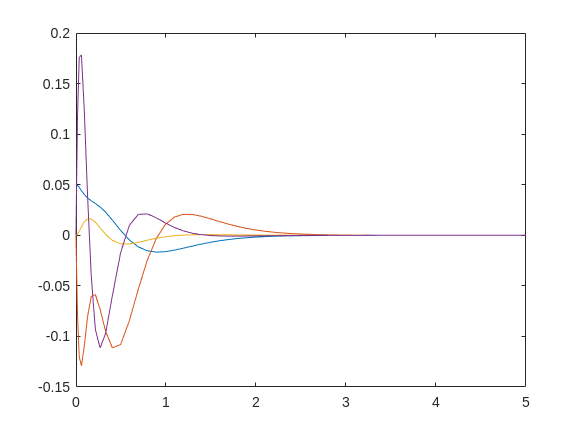

stObs.L = berechneBeobachter(stObs.A, stObs.C, stObs.poles)';
K = place(stObs.A, stObs.B, [-1.5, -2.5, -3.5, -4.5]);

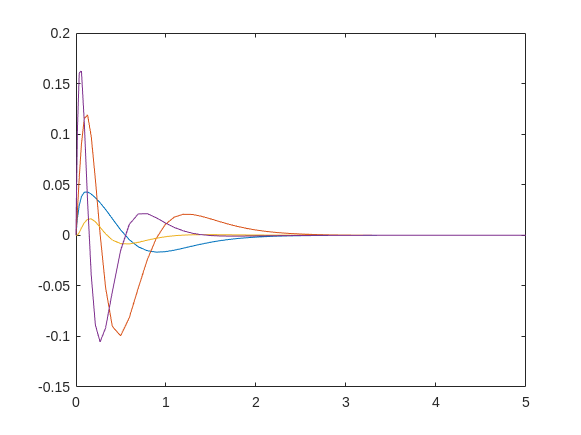

x0 = [0.05,0,0,0];
[vT, mX, mXobs] = runPendel(stPendel, AP,K,x0,stObs);

figure()
plot(vT,mX);
figure()
plot(vT,mXobs);

## GUI Teil 2

### Aufgabe 4

Erweitern Sie Ihre GUI um eine Auswahlmöglichkeit „Beobachter oder Zustandsrückführung“. Sehen Sie außerdem Eingabefelder für die Beobachtereigenwerte und die Anfangswerte für den Beobachter vor.

Erweitern Sie die Callback-Funktion der Schaltfläche derart, dass je nach Wahl ggfs. die Beobachtermatrix L berechnet und die Funktion runPendel entsprechend aufgerufen wird.

In Abbildung 1.1 ist ein Beispiel abgebildet, wie das finale GUI aussehen kann

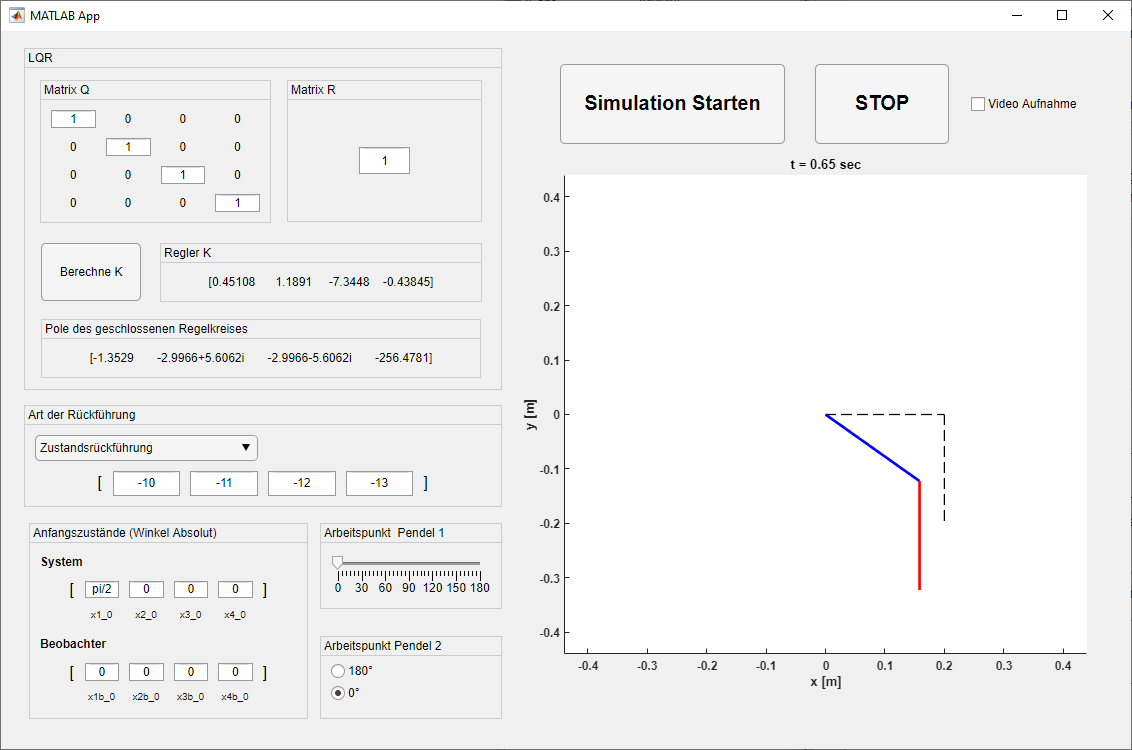

**Abbildung 1.1:** Mögliches Aussehen der GUI mit allen Funktionen

#### Ihre Antwort:

Keine Antwort notwendig!

**Code und Plots zu Ihrer Antwort:**

% Kein Code erforderlich!

### Aufgabe 5

Gehen Sie von


$$\mathbf{Q}=\textrm{diag}\left(\left\lbrack \begin{array}{cccc}
1 & 1 & 1 & 1
\end{array}\right\rbrack \right)$$



$$\mathrm{R}=1$$



$${\mathbf{x}}_0^{\top \;} =\left\lbrack \begin{array}{cccc}
3 & 0 & \pi \; & 0
\end{array}\right\rbrack$$



$${\mathbf{x}}_{\textrm{obs},0}^{\top \;} =\left\lbrack \begin{array}{cccc}
\pi  & 0 & \pi  & 0
\end{array}\right\rbrack$$



$${\mathbf{x}}_{\textrm{AP}}^{\top \;} =\left\lbrack \begin{array}{cccc}
\pi  & 0 & \pi \; & 0
\end{array}\right\rbrack$$


aus und untersuchen Sie anhand von ein paar Beispielen und geeigneten Graphen den Einfluss des Beobachters und der Beobachtereigenwerte auf die geschätzten Zustände und das Verhalten des Regelkreises. 

Was fällt bei den Werten für die gemessenen Zustände ${\mathrm{x}}_1$ und ${\mathrm{x}}_3$ auf? Wie könnte das Verhalten verbessert werden?

**Leiten Sie jede Betrachtung mit einer eigenen *****figure***** ein.**

#### Ihre Antwort:

**Code und Plots zu Ihrer Antwort:**

% Voreinstellungen
x0 = [3,0,pi,0];
x0obs = [pi,0,pi,0];
xAP = [pi,0,pi,0];
Q = eye(4);
R = 1;
stPendel = ladePendel();
[f,h] = nonlinear_model();
[A,B,C,D] = linearisierung(f,h,xAP);

% Regler
[K, poleRK] = berechneLQR(A, B, Q, R);


# Wichtige Anmerkung

**Strukturieren Sie ihren Code so, dass jede Sektion für sich ausführbar ist, und keine vorhergehenden Funktionen notwendig sind!** Muss beispielsweise ein Modell in mehreren aufgaben geladen werden, so laden Sie es in jedem Abschnitt erneut, insoweit nichts anderes angegeben ist.

Der Versuchsbericht in Form **dieses** Live Scriptes (einer pro Gruppe) ist anhand der oben aufgeführten Fragen anzufertigen und mit allen benötigten Funktionen innerhalb von einer Woche bei Moodle als Zip-File hochzuladen. Dafür ist eine sogenannte Datenbank bei Moodle hinterlegt. Bitte beachten Sie die zeitliche Begrenzung bis wann Sie die Unterlgen hochladen können. Wird ein Versuch nicht hochgeladen ist eine weitere Teilnahme am Praktikum nicht möglich. 

Bei jeder Aufgabe, in der eine Programmierung oder ein Skriptaufruf erforderlich ist, ist ein Codebereich definiert, indem sie alle notwendigen Befehle aufrufen können. Dieser Berich wird nicht bewertet. Alternativ können Sie ihre Zwischenrechnungen natürlich im Commandwindow oder in einem externen Skript aufrufen.

Ihre Textantworten sind stehts unter den Punkt ***Ihre Antwort****:* anzugeben. Antworten an anderer Stelle werden nicht bewertet!

Wird nach zu programmierenden Funktionen gefragt, ist ein Codefeld (bspw. *edit initModell.m*) hinterlegt, welches ein Grundgerüst zur Funktion aufruft. 

Im Praktikum kann es dazu kommen, dass Matrizen abgefragt werden. Im Bereich ***Code und Plots zu Ihrer Antwort ***sind die Variablen vordefiniert, jedoch ohne Inhalt. An dieser Stelle sind die Matrizen **ausgeschrieben** einzutragen. Bspw. berechnen Sie über eine Funktion eine Matrix $\left\lbrack \begin{array}{cc}
2 & 1\\
3 & 4
\end{array}\right\rbrack$. Diese ist dann im dafür vorgesehenen Codefeld ***Code und Plots zu Ihrer Antwort ***bei der passenden Variablen einzufügen. Beispiel:

% Vorgabe
A_vorgabe = -inf;
% Eigene Lösung
A_vorgabe = [2, 1; 3, 4];

Die Auswertung erfolgt teilautomatisiert.** Daher sind die Variablen auf keinen Fall umzubenennen.**

Sind Plots anzufertigen, wird danach explizit gefragt. Dabei sollte ein besonderer Wert auf die Aussagekraft der Diagramme und der Screenshots gelegt werden. Die Plots ***Code und Plots zu Ihrer Antwort ***sollen im Feld erstellt werden. Achten Sie darauf, dass sie einen neuen Plot stehts mit dem keyword *figure* neu beginnen. In der Regel ist dies jedoch vorgegeben.

Skalieren Sie die Diagramme sinnvoll, so dass das Ablesen bzw. Erkennen der interessierenden Größen möglich ist. In den Diagrammen ist eine eindeutige Achsenbezeichnung mit entsprechenden Größen und Einheiten unabdingbar. Bedenken Sie bei der Erstellung der Diagramme, dass diese auch schwarz/weiß ausgedruckt gut erkennbar und die einzelnen Graphen unterscheidbar sein müssen. Strukturieren Sie die Protokolle so, dass auch nach einer längeren Zeitpause ein rascher Einstieg in die Thematik möglich ist. Dies kann im späteren Berufsleben eine erhebliche Zeitersparnis mit sich bringen.

Eines der wichtigsten Hilfsmittel ist das Sektionsweise aufrufen. Das Live Script ist in Sektionen unterteilt. Diese können jeweils über den Punkt *Run Section* im oberen Bereich der Matlab Toolbar unter dem Punkt *Live Editor* oder per Tastenkombination **Strg + Enter **ausgeführt werden.

## Platz für Funktionen

## Platz für persönliche Hilfsfunktionen